## **Data Preperation**

fs = sparse(features)

fs =    (1,1)      16.1200
   (2,1)      16.1900
   (3,1)      18.8300
   (4,1)      10.7900
   (5,1)      14.1600
   (6,1)      12.8800
   (7,1)      14.7900
   (8,1)      13.7400
   (9,1)      18.2700
  (10,1)      20.7100
  (11,1)      13.3400
  (12,1)      20.8800
  (13,1)      15.6900
  (14,1)      11.4800
  (15,1)      12.4900
  (16,1)      18.8500
  (17,1)      17.3200
  (18,1)      12.1100
  (19,1)      12.0200
  (20,1)      12.1500
  (21,1)      18.3000
  (22,1)      12.7900
  (23,1)      10.8200
  (24,1)      13.2200
  (25,1)      20.1000
  (26,1)      14.8600
  (27,1)      16.2000
  (28,1)      19.3100
  (29,1)      12.0800
  (30,1)      16.8200
  (31,1)      16.7700
  (32,1)      13.4500
  (33,1)      13.1600
  (34,1)      19.1500
  (35,1)      18.9800
  (36,1)      11.2600
  (37,1)      15.3800
  (38,1)      16.1700
  (39,1)      14.9900
  (40,1)      12.3600
  (41,1)      14.1100
  (42,1)      14.4300
  (43,1)      11.1800
  (44,1)      13.5400
  (45,1)      18.1400
  (46


libsvmwrite('svm', labels, fs);

[y,x] = libsvmread('svm');

trainlabel = y(1:170,:);

traindata = x(1:170,:);

testdata = x(171:210,:);

testlabel = y(171:210,:);

## Data Training

model = svmtrain(trainlabel, traindata, '-s 0 -t 1 -d 2 -g 2.8 -b 1');

................................................*..............*
optimization finished, #iter = 5676
nu = 0.000433
obj = -0.019703, rho = -11.179568
nSV = 7, nBSV = 0
Total nSV = 7
....................................*......................*
optimization finished, #iter = 5224
nu = 0.000632
obj = -0.028462, rho = -14.961808
nSV = 7, nBSV = 0
Total nSV = 7
.................................*.........*
optimization finished, #iter = 3896
nu = 0.000346
obj = -0.015757, rho = -17.052835
nSV = 7, nBSV = 0
Total nSV = 7
...................................*......................*
optimization finished, #iter = 5139
nu = 0.000632
obj = -0.028462, rho = -14.961145
nSV = 7, nBSV = 0
Total nSV = 7
................................*...........*
optimization finished, #iter = 3948
nu = 0.000555
obj = -0.024998, rho = -30.168556
nSV = 6, nBSV = 0
Total nSV = 6
...........................*.................*
optimization finished, #iter = 5046
nu = 0.000504
obj = -0.028462, rho = -14.960592
nSV = 7, nBS

## Testing the Data

[predicted_labeltest] = svmpredict(testlabel, testdata, model, '-q');

## Results

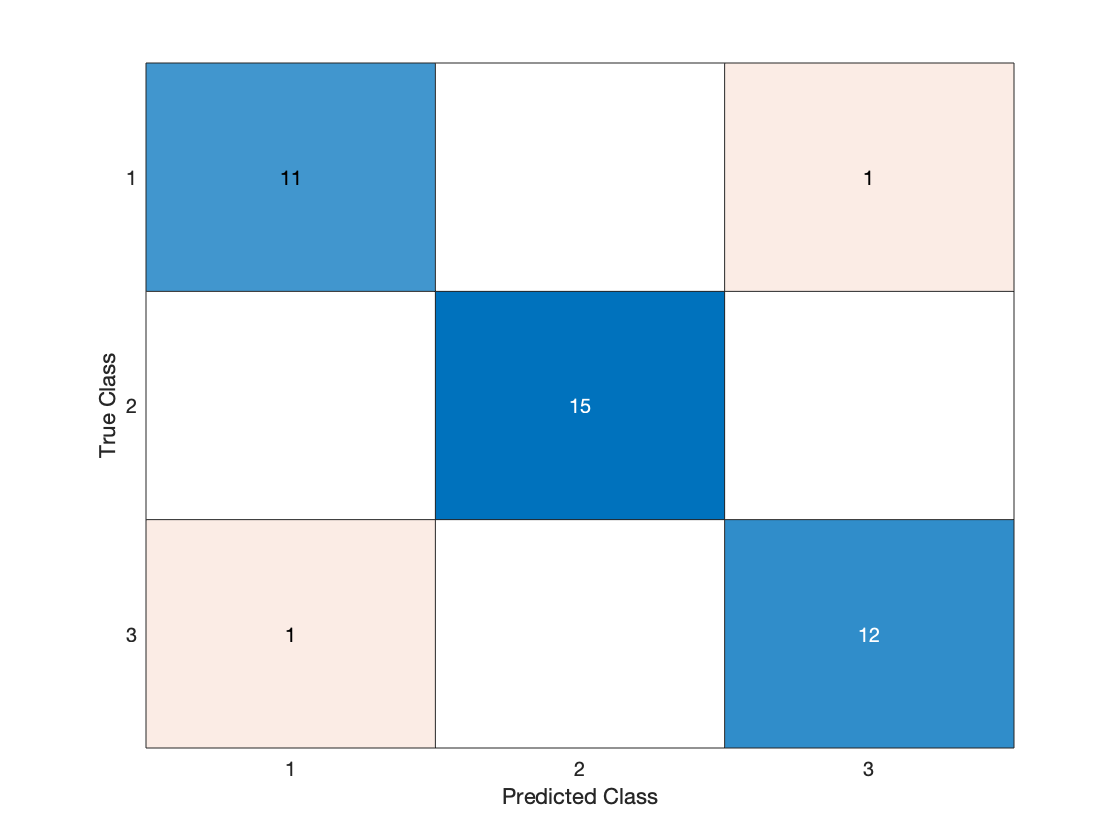

chart =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [1 2 3]

  Show all properties


chart = confusionmat(testlabel, predicted_labeltest);
chart = confusionchart(chart)


wrongPredictionsArr = testlabel == predicted_labeltest;
wrongPredictions = sum(wrongPredictionsArr(:) == 0);
noe = numel(testlabel);
rate = ((noe-wrongPredictions)/noe)*100

rate = 95

## ALL DATA

model = svmtrain(trainlabel, traindata, '-s 0 -t 1 -d 2 -g 2.8 -b 1');

................................................*..............*
optimization finished, #iter = 5676
nu = 0.000433
obj = -0.019703, rho = -11.179568
nSV = 7, nBSV = 0
Total nSV = 7
....................................*......................*
optimization finished, #iter = 5224
nu = 0.000632
obj = -0.028462, rho = -14.961808
nSV = 7, nBSV = 0
Total nSV = 7
.................................*.........*
optimization finished, #iter = 3896
nu = 0.000346
obj = -0.015757, rho = -17.052835
nSV = 7, nBSV = 0
Total nSV = 7
...................................*......................*
optimization finished, #iter = 5139
nu = 0.000632
obj = -0.028462, rho = -14.961145
nSV = 7, nBSV = 0
Total nSV = 7
................................*...........*
optimization finished, #iter = 3948
nu = 0.000555
obj = -0.024998, rho = -30.168556
nSV = 6, nBSV = 0
Total nSV = 6
...........................*.................*
optimization finished, #iter = 5046
nu = 0.000504
obj = -0.028462, rho = -14.960592
nSV = 7, nBS

[predicted_labeltest, accuracy, prob_estimates] = svmpredict(labels, fs, model, '-b 1');

Accuracy = 96.6667% (203/210) (classification)


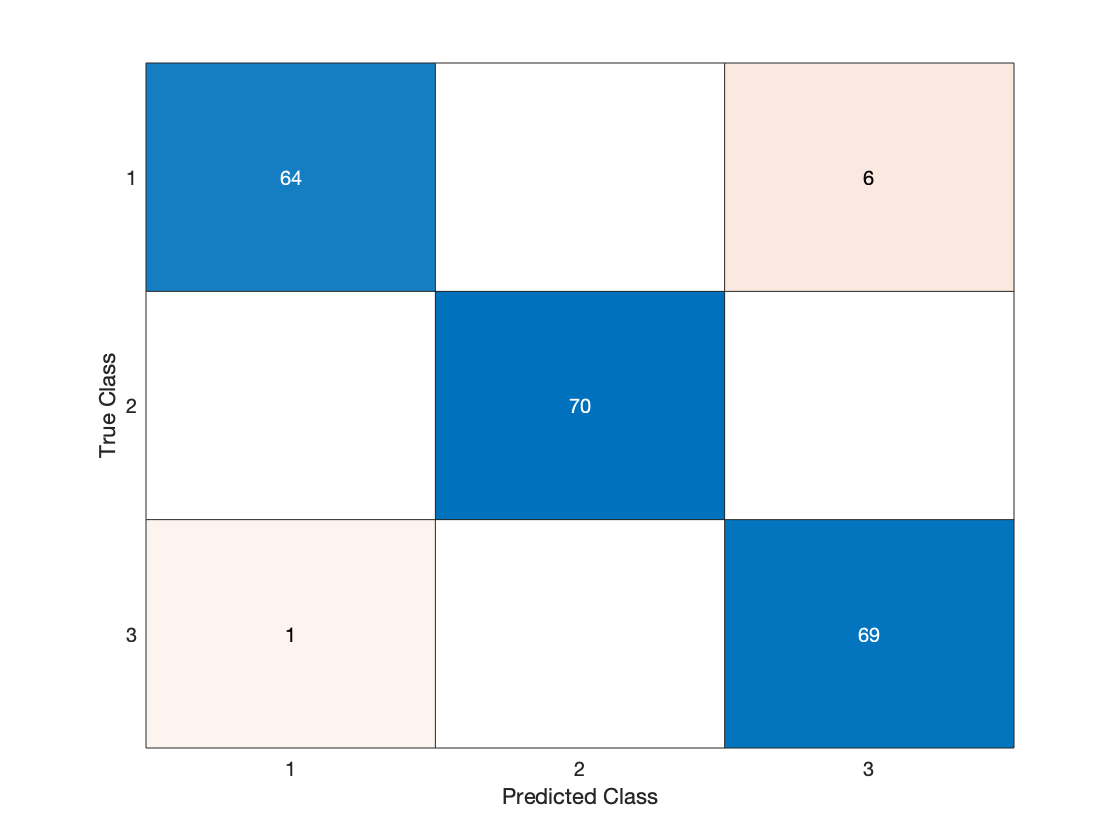

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [1 2 3]

  Show all properties


confusionmat(labels, predicted_labeltest);
confusionchart(ans)